# Max_Vogel_InertialSensorLabAnalysis

This script analyzes mobile phone inertial sensor data collected from a pendulumn system. The apparatus and methods are described on [Canvas](https://canvas.wisc.edu/courses/223849/quizzes/201501/take).

Specifically, we hope to estimate a value for gravity by measuring taking the acceleramator and gyroscope data from a pendulumn and using the equation $T=2\pi \;\sqrt{\frac{L}{g}}\left(1+\frac{1}{16}\theta_0^2 +\frac{11}{3072}\theta_0^4 +\ldotp \ldotp \ldotp \right)$ where $\theta$ will be sufficiently small so we can assume the latter term is 1 ([small-angle approximation](https://en.wikipedia.org/wiki/Pendulum_(mathematics))).

Author: Max Vogel

Date: 10/7/2020

Collaborators: Asa Hooper-Lane, Jaden Sengkhammee, Shirya Goyal -- helped troubleshoot during lab.

Contributions: John Podczerwinski for recording data and Professory Carlsmith for creating this template.

## Import sensor data

We'll use the phyphox app to collect the data. The phone's linear acceleration has a left-right component and an up-down component. The phone gyro sensors will provide simultaneous measurements of the angular acceleration of the phone about its instantaneous axes. The app generates a csv, so we'll import it with the `readtable` command.

When we open the data tables, we'll go ahead and make a variable for reach row. For the time, we'll subtract the whole array from the first value to zero the vector.

acc = readtable('./phys_pendulum_1/small_angle_1/Linear Acceleration.csv'); %read in acceleration data

gyro = readtable('./phys_pendulum_1/small_angle_1/Gyroscope.csv'); %read in angular velocity data


ta = acc.Time_s_(:)-acc.Time_s_(1); % make a vector with the times for linear acc. data and "zero" the data
ax = acc.LinearAccelerationX_m_s_2_(:); %x-component of a
ay = acc.LinearAccelerationY_m_s_2_(:); %y-component of a 
az = acc.LinearAccelerationZ_m_s_2_(:); %z-component of a 

tw = gyro.Time_s_(:)-gyro.Time_s_(1); %make a vector with the times for angular vel data and "zero" the data
wx = gyro.GyroscopeX_rad_s_(:); %x-component of angular vel
wy = gyro.GyroscopeY_rad_s_(:); %y-component 
wz = gyro.GyroscopeZ_rad_s_(:); %z-component 

## (A) Plots of raw data

We'll plot our linear accelartion in the x and y axis, as well as the angular acceleration in the z axis. The linear acceleration in the y direction is scaled to be 5 times as large, and the angular acceleration is scaled twice as large.

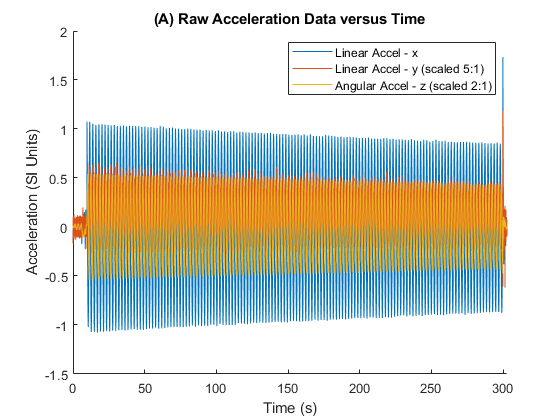

figure()
hold on 

plot(ta,ax)
plot(ta,ay*5)
plot(tw,wz*2)

xlim([0 max(ta(end), tw(end))])
ylim auto;

xlabel('Time (s)')
ylabel('Acceleration (SI Units)')
title('(A) Raw Acceleration Data versus Time')
legend("Linear Accel - x", "Linear Accel - y (scaled 5:1)", "Angular Accel - z (scaled 2:1)");
%xlim([10 50])
hold off

## (B) Superposing Equation

We'll create a ad-hoc equation for the z-component of angular velocity. This should follow the equation $\omega \left(t\right)={A\;e}^{-\frac{t}{\tau }} \cdot \mathrm{sin}\left(\omega_0 t+\phi \right)$. We'll start by selecting the time frame where the data does not contain outliers (towards the beginning and end).

tstart=9.696; % release of arm
tend=298.8; % end
trange = tw>tstart&tw<tend;

Then we'll plot our data and change the axis to fit our range.

figure();
hold on
plot(tw,wz)
xlim([tstart tend]);

We'll then find the peeks of our function. To find $\omega_0$ we'll measure distance between peaks and divide by the number of peaks between to find the period. We'll take arbitrary points `10` and `end - 5`, then plug them into our equation.

[pk_height,pk_time] = findpeaks(wz(trange), ...
    'MinPeakHeight',.2, ...
    'MinPeakWidth', 45 ...
    );

n = size(pk_height);
n = n(1)*.5;

pk_ti = tw(pk_time(10)); 
pk_tf = tw(pk_time(end-5));

w0 = (pk_tf-pk_ti)/(n)

w0 = 2.9581

$A$ is the amplitude, so we can just take the maximum peak:

A = max(wz(trange))

A = 0.2726

$\tau$ we can estimate by picking a peek at time $t_1$ and height $\omega {\;}_{\mathrm{t1}}$. We'll then pick another point far away at time $t_1$ and height $\omega_{\textrm{t2}}$. With this, we can take a ratio of $\frac{\omega \left(t_1 \right)}{\omega \left(t_2 \right)}$, and when we simplify it will we will have sin = 1 (the max of sin). Simplifying, we get $\tau =\frac{\left(t_2 -t_1 \right)}{\mathrm{ln}\left(\frac{\omega_{\mathrm{t1}} }{\omega_{\mathrm{t2}} }\right)}$.

pk_hi = pk_height(10); 
pk_hf = pk_height(end-5);
tau = ((pk_tf -  pk_ti) / log(pk_hi/pk_hf))

tau = 1.3059e+03

To find phi, we'll shift our data over so our data is in-phase with the fit equation

phi = tstart

phi = 9.6960

We can then plot our equation ontop of the figure

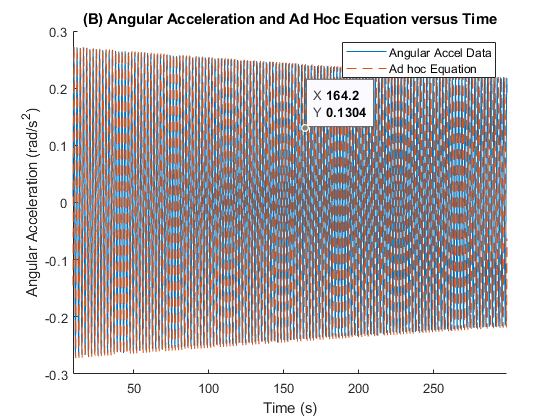

adhoc = A * exp(-tw/tau) .* sin(w0/1.008 * (tw+phi+w0));
plot(tw+phi, adhoc,'--')
xlabel('Time (s)')
ylabel('Angular Acceleration (rad/s^2)')
title('(B) Angular Acceleration and Ad Hoc Equation versus Time')
legend("Angular Accel Data", "Ad hoc Equation");

## (C) Comparing large and small angle data

We'll go ahead and import our large angle data the same way we did with small angle data.

large_acc = readtable('./phys_pendulum_1/big_angle_1/Linear Acceleration.csv'); %read in acceleration data

large_gyro = readtable('./phys_pendulum_1/big_angle_1/Gyroscope.csv'); %read in angular velocity data


large_ta = large_acc.Time_s_(:)-large_acc.Time_s_(1); % make a vector with the times for linear acc. data and "zero" the data
large_ax = large_acc.LinearAccelerationX_m_s_2_(:); %x-component of a
large_ay = large_acc.LinearAccelerationY_m_s_2_(:); %y-component of a 
large_az = large_acc.LinearAccelerationZ_m_s_2_(:); %z-component of a 

large_tw = large_gyro.Time_s_(:)-large_gyro.Time_s_(1); %make a vector with the times for angular vel data and "zero" the data
large_wx = large_gyro.GyroscopeX_rad_s_(:); %x-component of angular vel
large_wy = large_gyro.GyroscopeY_rad_s_(:); %y-component 
large_wz = large_gyro.GyroscopeZ_rad_s_(:); %z-component 

We can then go ahead and plot the linear acceleration

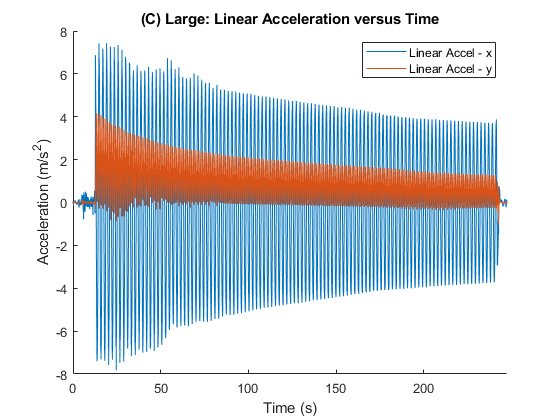

figure()
hold on 

plot(large_ta,large_ax)
plot(large_ta,large_ay)

xlim([0 large_ta(end)])
ylim auto;
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('(C) Large: Linear Acceleration versus Time')
legend("Linear Accel - x", "Linear Accel - y");
hold off

We'll also plot angular acceleration on a seperate graph

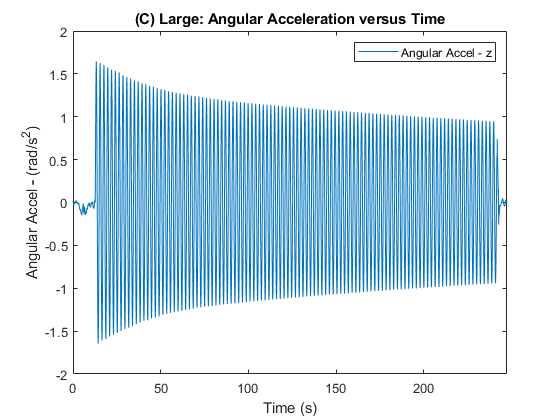

figure()
plot(large_tw, large_wz)
xlim([0 large_tw(end)])
ylim auto;
xlabel('Time (s)')
ylabel('Angular Accel - (rad/s^2)')
title('(C) Large: Angular Acceleration versus Time')
legend("Angular Accel - z");

**Takeaways: **Comparing the  large angle data, we can see that it it's less uniform than the small angle data. Whereas the small angle data could be bound by an almost linear line, the large angle would need to be bound by a quadratic line. Moreover, the large angle data seems to have distortion for the linear acceleration in the x direction towards the beginning (around the 25-50 second range). This should be taken with consideration that the large angle data sample wasn't taken for as long as the short angle data (it's about 2/3 the length).

## (D) Estimating Gravity

We can now use our data to estimate the local acceleration of gravity by using the equation $T=2\pi \;\sqrt{\frac{L}{g}}\left(1+\frac{1}{16}\theta_0^2 +\frac{11}{3072}\theta_0^4 +\ldotp \ldotp \ldotp \right)$ and we'll use the small angle data so that the angle is sufficiently small enough that we can consider the last term to be essentially 1 (ignoring it).

We'll go ahead and define our constants (measured from the images)

L_bar = (171.75-2.85)/100; % m
width = 100.05-98.95; % cm

We can then rewrite our equation so that it solves for  g, then substitute in our values

syms L g
peroid = T == 2*pi*sqrt(L/g)

$$peroid = T=2\,\pi \,\sqrt{\frac{L}{g}}$$

g = solve(peroid, g)

$$g = \frac{4\,L\,\pi^{2}}{T^{2}}$$

g = subs(g, L, L_bar);
g = subs(g, T, w0);
g_estimate = double(g)

g_estimate = 7.6204

Our estimated g is 7.62 m s^-2. This could be due to errors in our data. First, there may be some amount of standard uncertainty. Standard uncertainty could come  from  how accurately we measure our values. For example, the measured value for the length of the pendulumn may have been accidentaly measured at an angle such that it's value was measured to be too short by 0-15%. Additionally, there may have been some amount of friction about the axis that the pendulumn pivoted about such the period was found to be longer than expected by a value was off by 0-15%. We can set up an equation for uncertainty, and plug in our  values to find the range.

syms g T L deltaL deltaT g_uncert

L_err = 0.15; % %
T_err = 0.15; % %

g_uncert = sqrt(((2*g)/(2*L) * deltaL)^2 + ((2*g)/(2*T) * deltaT)^2)

$$g\_uncert = \sqrt{\frac{{\mathrm{deltaL}}^{2}\,g^{2}}{L^{2}}+\frac{{\mathrm{deltaT}}^{2}\,g^{2}}{T^{2}}}$$

g_uncert = subs(g_uncert, g, g_estimate);
g_uncert = subs(g_uncert, L, L_bar);
g_uncert = subs(g_uncert, T, w0);
g_uncert = subs(g_uncert, deltaL, L_err);
g_uncert = subs(g_uncert, deltaT, T_err);
double(g_uncert)

ans = 0.7793

This value of `.7793 `means that the true value likely falls within the a range of $7\ldotp 62\pm 0\ldotp 7793$

Moreover, there may also be factors that contibute to systematic uncertainty. This could be the drag force excerted on the pendulumn that we didn't account for. This would have resulted in a longer peroid, exponentially decreasing our estimated g.